# Example 4.3: Estimation for Weibull using Least-Squares

Note: this script reproduces Example 4.3 (Section 4.1.2) of **Statistics for Chemical Engineers**: fitting the Weibull cdf to the empirical cdf. Victor Z UW-Madison, 2020 least-squares fit of weibull

clc; clear all; close all hidden;

## Data

generate observations for weibull

S = 100;
rng(1);

beta=1 %(scale)

beta =      1

xi=2 %(shape)

xi =      2


xdata = wblrnd(beta,xi,S,1);

## Empirical cdf

assume Weibull model and fit to cdf

% generate thresholds and ecdf at thresholds
N = 20;
t = linspace(min(xdata),max(xdata),N);

for k=1:length(t)
   s=0;
   for j=1:S
       if xdata(j)<=t(k)
           s=s+1;
       end
   end
   F(k)=(1/S)*s;
end

% drop last term 
t=t(1:N-1);
F=F(1:N-1);

## Least-squares fit (numerical)

solve least squares problem

theta=[1,1]; % initial guess for parameters
opt= optimoptions('fmincon','Display','iter','Algorithm','sqp','OptimalityTolerance',1e-10);
theta=fmincon(@lsfunc,theta,[],[],[],[],[],[],[],opt,t,F);

 Iter  Func-count            Fval   Feasibility   Step Length       Norm of   First-order   Wall-Clock Time  
                                                                       step    optimality
    0           3    1.039239e-01     0.000e+00     1.000e+00     0.000e+00     3.169e-01      0.052555 sec  
    1           6    3.784818e-02     0.000e+00     1.000e+00     3.176e-01     1.280e-01      0.069452 sec  
    2           9    2.217528e-02     0.000e+00     1.000e+00     3.664e-01     2.628e-01      0.071231 sec  
    3          12    4.965634e-03     0.000e+00     1.000e+00     1.153e-01     3.706e-02      0.072754 sec  
    4          15    1.945041e-03     0.000e+00     1.000e+00     1.180e-01     1.735e-02      0.074233 sec  
    5          18    9.820280e-04     0.000e+00     1.000e+00     9.401e-02     5.810e-03      0.075709 sec  
    6          21    8.944154e-04     0.000e+00     1.000e+00     3.512e-02     4.941e-04      0.077192 sec  
    7          24    8.931918e


% get optimal estimates
betahat=theta(1) % scale parameter

betahat =    1.0448e+00

xihat=theta(2)   % shape parameter

xihat =    1.9570e+00

## Least-squares fit (log transformation)

alternatively, we can solve least-squares problem (analytically) using log transformation

 x = log(t);
 y = log(-log(1 - F));
 
 my=mean(y);
 mx=mean(x);
 theta1=sum(x.*(y-my))/sum(x.*(x-mx))

theta1 =    1.8968e+00

 theta0=my-theta1*mx

theta0 =   -1.6001e-01

 
 % get estimates
 xilin=theta1

xilin =    1.8968e+00

 betalin=exp(-theta0/xilin)

betalin =    1.0880e+00

## Comparison

compare model cdf (with LS estimates) to empirical cdf

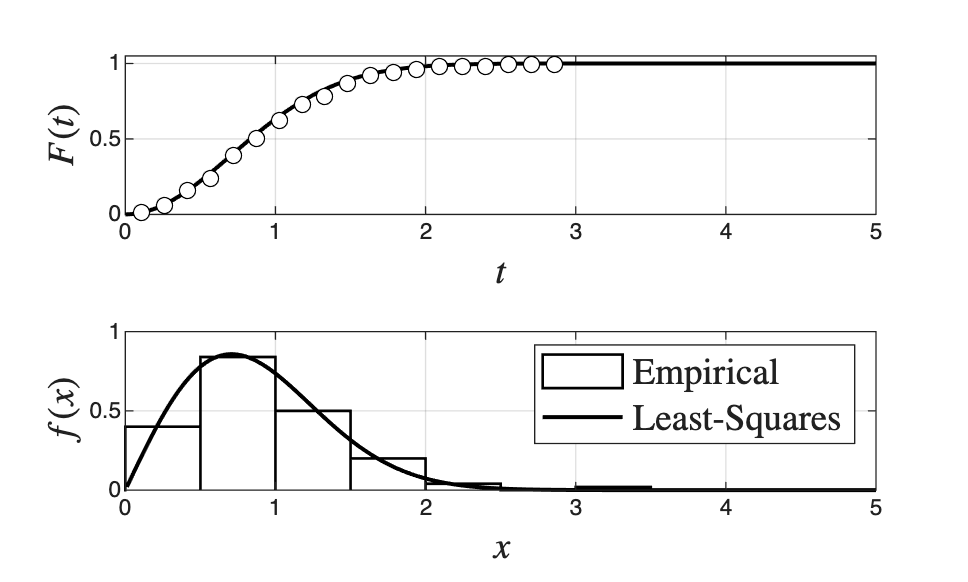

figure(2)
subplot(2,1,1)
tgrid=linspace(0,5,100);
plot(tgrid,wblcdf(tgrid,beta,xi),'black-','LineWidth',1.5);
hold on
plot(t,F,'blacko','MarkerFaceColor','w')
xlabel('$t$','Interpreter','latex','FontSize',14) 
ylabel('$F(t)$','Interpreter','latex','FontSize',14)
axis([0 5 0 1.05])
grid on
subplot(2,1,2)
xgrid=linspace(0.01,16,1000);
histogram(xdata,'BinWidth',0.5,'Normalization','pdf','EdgeColor','black','FaceColor','none','LineWidth',1)
hold on
plot(xgrid,wblpdf(xgrid,beta,xi),'black-','LineWidth',1.5);
axis([0 5 0 1])
xlabel('$x$','Interpreter','latex','FontSize',14)
ylabel('$f(x)$','Interpreter','latex','FontSize',14)
grid on
legend({'Empirical','Least-Squares'},'location','northeast','Interpreter','latex','FontSize',14)
print -depsc ch4_weibull_ls_fit.eps

## define function to optimize by LS

function LS=lsfunc(theta,t,F)

% evaluate the cdf of the Weibull model

Fmod= wblcdf(t,theta(1),theta(2));

% define squared errors
e = (F-Fmod).^2;

% define LS function
LS = (1/2)*sum(e);

end

## Note

As in the book, the estimates (beta of about 1.08, xi of about 1.89) are close to the true values; the numerical and analytical (log-transformed) fits differ slightly.